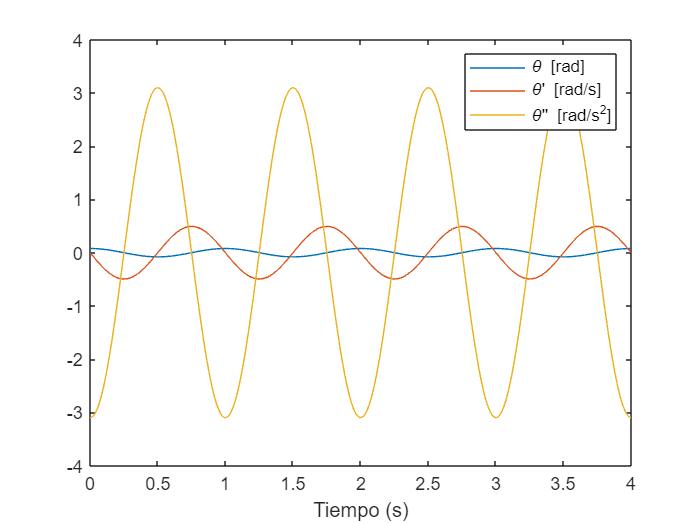

clc; 
clear;

g=9.8;

T=1;
d=g*(T/2/pi)^2;

T0=4*T;

m = 1.1;

vdp=@(t,y)[y(2); -g/d*sin(y(1))];

[t,y]=ode45(vdp,[0:0.01:T0],[pi/40;0]);

y2p=-g/d*sin(y(:,1));
%Resolución de la EDO
figure;
plot(t,y,t,y2p)
xlabel('Tiempo (s)');
legend('\theta [rad]','\theta'' [rad/s]','\theta'''' [rad/s^{2}]')

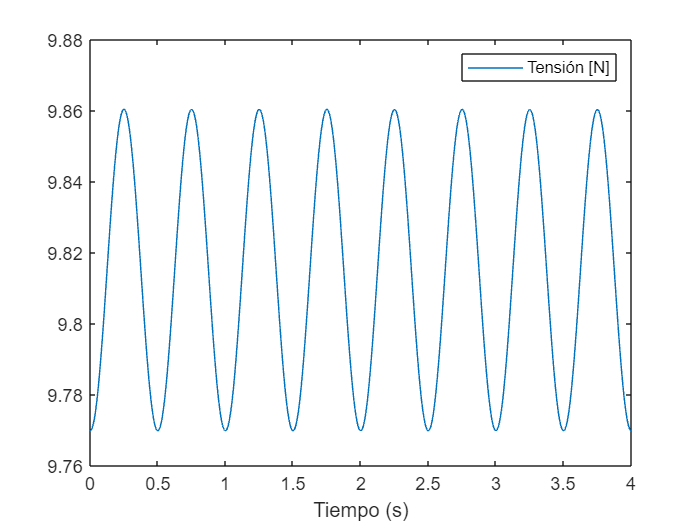

%Cálculo de tensión
figure;
T = (g*cos(y(:,1))+y(:,2).^2*d);
plot(t,T)
legend('Tensión [N]');
xlabel('Tiempo (s)');

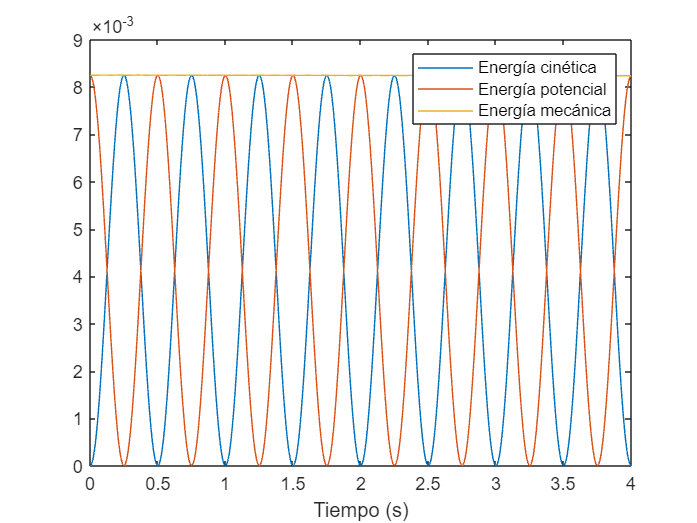

%Cálculo de energías
figure;
K = 0.5*m*y(:,2).^2*d^2;
U = m*g*d*(1-cos(y(:,1)));
E=K+U;
plot(t,K,t,U,t,E)
legend('Energía cinética (J)','Energía potencial (J)','Energía mecánica (J)');
xlabel('Tiempo (s)');